##  Practical Problems 5 – Open Root Finding Methods

Plotting the function is a good idea to get an idea of where the roots are and provide initial guesses, then the methods can be used to get an accurate estimation. 

You can also substitute your answers back into the equation to see if it is correct (anonymous functions can help with that).

1. Use the **roots** function to find the roots of the polynomial.

pRoots = roots([1, 0, -10, 0, 21, 0])

pRoots =          0
   -2.6458
   -1.7321
    2.6458
    1.7321


2. Create an anonymous function for p(x) and substitute the roots you found in question 1 into it to verify your answer.

p = @(x) x.^5 - 10 * x.^3 + 21 * x;
p(pRoots)

ans = 1.0e-12 *

         0
   -0.1705
   -0.0568
   -0.0995
    0.0142


3. Use the **roots** function to find the roots of the polynomial (no template). Display only the real roots.

qRoots = roots([-2, 0, -1.5, 0, 0, 10, 2])

qRoots =    1.3213 + 0.0000i
   0.4201 + 1.4191i
   0.4201 - 1.4191i
  -0.9809 + 0.8761i
  -0.9809 - 0.8761i
  -0.1997 + 0.0000i


qReal = qRoots(abs(imag(qRoots)) < 1e-10)

qReal =     1.3213
   -0.1997


4. Use the **fzero** function to locate all roots of  

on the interval [0,5]. Plot the function with a grid and mark the roots with large green diamonds. For this question make a function file to hold the function. You will have to divide the interval into pieces using an appropriate step size, h. First try h = 2, then plot the function and roots to see if it found them all. If not, adjust your value of h and try again.

xAxis = 0:0.01:5;
answ = [];
f = @(x) exp(x) .* cos(x).^2 - 2;
for n = 0 : 5
    poAns = fzero(f, n);
    tolerance = 1e-4;
    residuals = f(poAns);
    if max(abs(residuals)) < tolerance
        if isempty(answ)
            answ(end + 1) = poAns;
        else 
            if answ(end) ~= poAns
                answ(end + 1) = poAns;
            end
        end
    end
end
answ

answ =     2.0911    4.5678    4.8386


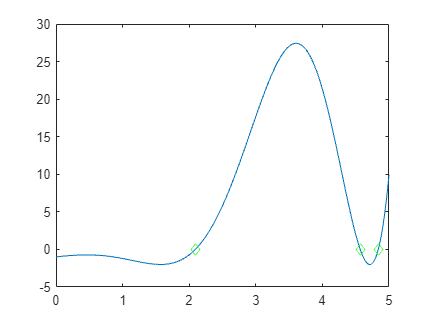

plot(xAxis, f(xAxis))
hold on
plot(answ, f(answ), 'd', "Color", 'g')
hold off

5. Write a script that solves

using Fixed Point Iteration. Choose your own stopping criteria and keep track of the error at each iteration. Keep in mind that you can choose any of the following 4 formulas for your fixed point iteration:

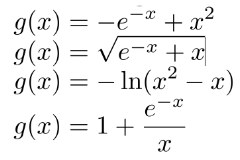

Test all of them to see which work and which don’t.

iteration = 10;
initialGuess = 1.1;
syms x
h = (x^2) - x - exp(-x);
g1 = -exp(-x) + x^2;
g2 = sqrt(exp(-x)+x);
g3 = -log((x^2)-x);
g4 = 1 + (exp(-x)/x);

funcCell = cell(4);
funcCell = {g1, g2, g3, g4};

for n = 1:4
    disp("Function " + num2str(n))
    diffEq = diff(funcCell{n});
    x = initialGuess;
    if abs(double(subs(diffEq))) > 1
        disp("Derivative larger than 1")
    else
        yAns = initialGuess;
        for m = 1 : iteration
            x = yAns;
            yAns = double(subs(funcCell{n}));
            disp("Iteration " + num2str(m) + ": " + num2str(yAns))
        end
    end
end

Function 1


Derivative larger than 1


Function 2


Iteration 1: 1.197
Iteration 2: 1.2244
Iteration 3: 1.2322
Iteration 4: 1.2344
Iteration 5: 1.2351
Iteration 6: 1.2353
Iteration 7: 1.2353
Iteration 8: 1.2353
Iteration 9: 1.2353
Iteration 10: 1.2353


Function 3


Derivative larger than 1


Function 4


Iteration 1: 1.3026
Iteration 2: 1.2087
Iteration 3: 1.247
Iteration 4: 1.2304
Iteration 5: 1.2375
Iteration 6: 1.2345
Iteration 7: 1.2357
Iteration 8: 1.2352
Iteration 9: 1.2354
Iteration 10: 1.2353


6. Write a function that takes an initial guess as input then locates a root of 

using the Newton-Raphson Method. Remember you will have to differentiate the function to get the formula. Choose your own convergence criterion.

tolerance = 0.0001;
curTor = 1000;
initialGuess = 5;

syms x
r = sin(x) * cos(2 * x);
rDiff = diff(r);
newtonRaphson(initialGuess, r, rDiff, tolerance)

ans = 5.4978

7. Use your function from question 6 to find all roots of r(x) on the interval [–π,π].

syms x x1 x2
tolerance = 0.0001;
y = sin(x) * cos(2 * x);
yArr = sin(x) .* cos(2 .* x);
yDiff = diff(y);
answ = [];
for n = linspace(-pi,pi,100)
    a = newtonRaphson(n, y, yDiff, tolerance);
    if (-pi <= a)
        if (a <= pi)
            answ(end + 1) = a;
        end
    end
end
answ = unique(answ)

answ =    -3.1416   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -2.3562   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.7854   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854    0.7854


x3 = linspace(-pi,pi,100);
y3 = sin(x3) .* cos(2 .* x3);
yDot = sin(answ) .* cos(2 .* answ)

yDot = 1.0e-07 *

   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0071    0.0270    0.1193    0.0523    0.0373    0.0231    0.0093    0.0065    0.0033    0.0026    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0006   -0.0026


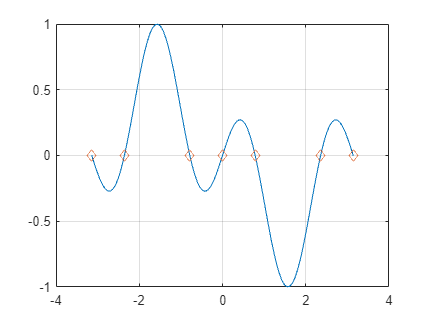

plot(x3, y3)
hold on
plot(answ, yDot, 'd')
hold off
grid on

Functions

function aOut = newtonRaphson(xi, fx, fPrimeX, maxTol)
    x1 = xi;
    xBef = 0;
    delta = 10000;
    while delta > maxTol
        xBef = x1;
        x = x1;
        x1 = x1 - (double(subs(fx))/double(subs(fPrimeX)));
        delta = abs(x1 - xBef);
    end
    aOut = x1;
end

8. Write a script that locates all roots of  

using the Bisection Method. Locate brackets by using the incremental search method you wrote before.